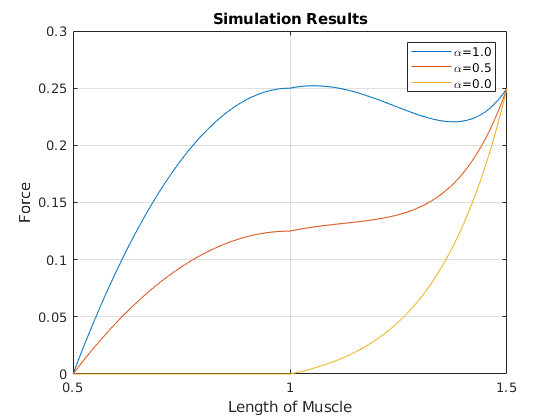

%%% Variables %%% 
l_o = 1;
T_max = (.5*l_o)^2;
xpmax= 0.5*l_o;
ks = 3;
l = [0.0:0.01:1.5];

%%% Part 1 %%% 

% Alpha = 1.0
alpha = 1;
T_a = -alpha*((l-l_o).^2-T_max);
T_a(l<0.5) = 0;
xp = l - l_o;
T_p = vpa(T_max/(exp(ks)-1))*(exp(ks*xp./xpmax)-1);
T_p(l<1.0) = 0;
T = T_a + T_p;
plot(l,T)
hold on

% Alpha = 0.5
alpha = 0.5;
T_a = -alpha*((l-l_o).^2-T_max);
T_a(l<0.5) = 0;
xp = l - l_o;
T_p = vpa(T_max/(exp(ks)-1))*(exp(ks*xp./xpmax)-1);
T_p(l<1.0) = 0;
T = T_a + T_p;
plot(l,T)

% Alpha = 0.0
alpha = 0;
T_a = -alpha*((l-l_o).^2-T_max);
T_a(l<0.5) = 0;
xp = l - l_o;
T_p = vpa(T_max/(exp(ks)-1))*(exp(ks*xp./xpmax)-1);
T_p(l<1.0) = 0;
T = T_a + T_p;
plot(l,T)

grid on
axis([.5 1.5 0 0.3])
xlabel('Length of Muscle')
ylabel('Force')
title('Simulation Results')
legend('\alpha=1.0','\alpha=0.5','\alpha=0.0')


%%% Part B %%%

% Alpha = 1.0
alpha = 1;
T_a = -alpha*((l-l_o).^2-T_max);
T_a(l<0.5) = 0;
xp = l - l_o;
T_p = vpa(T_max/(exp(ks)-1))*(exp(ks*xp./xpmax)-1);
T_p(l<1.0) = 0;
T = T_a + T_p;

T_unstable = [1.05, 1.37]

T_unstable =     1.0500    1.3700


unstable = [T(l==1.05), T(l==1.37)]

$$unstable = \left(\begin{array}{cc} 0.25208277397413624815205865494874 & 0.22060720426302091326369790923792 \end{array}\right)$$

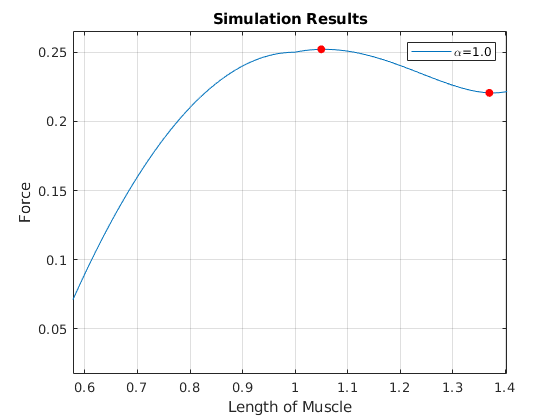

figure(2)
plot(l,T)
hold on
scatter(T_unstable,unstable,'filled','r')

grid on
axis([.5 1.5 0 0.3])
xlabel('Length of Muscle')
ylabel('Force')
title('Simulation Results')
legend('\alpha=1.0')

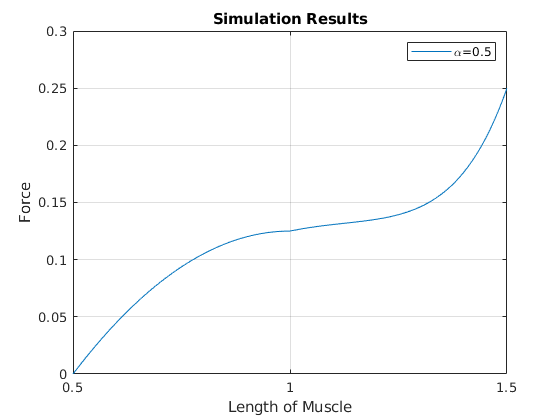


%%%%% Part C %%%%

% Alpha = 0.5
alpha = 0.5;
T_a = -alpha*((l-l_o).^2-T_max);
T_a(l<0.5) = 0;
xp = l - l_o;
T_p = vpa(T_max/(exp(ks)-1))*(exp(ks*xp./xpmax)-1);
T_p(l<1.0) = 0;
T = T_a + T_p;
figure(3)
plot(l,T)

grid on
axis([.5 1.5 0 0.3])
xlabel('Length of Muscle')
ylabel('Force')
title('Simulation Results')
legend('\alpha=0.5')